# AE 709 HW 4

clear; close; clc;

## Initialize variables

% Material Properies
% tensile stiffness properties
E_1 = convpres(18.7E6,"psi","Pa"); % Tensile Youngs modulus in principal direction (Pa)
E_2 = convpres(1.9E6,"psi","Pa"); % Tensile Youngs modulus in transverse direction (Pa)

% compressive stiffness properties
E_1_c = convpres(17.6E6,"psi","Pa"); % Compressive Youngs modulus in principal direction (Pa)

% shear stiffness properties
G_12 = convpres(.85E6,"psi","Pa"); % Shear modulus in plane (Pa)
nu_12 = .3; % possion's ratio in plane (Pa)

% tensile allowable properties
F_1_t = convpres(274E3,"psi","Pa"); % Tensile failure stress in principal direction (Pa)
F_2_t = convpres(9.5E3,"psi","Pa"); % Tensile failure stress in transverse direction (Pa)

% compressive allowable properties
F_1_c = convpres(-279.6E3,"psi","Pa"); % Tensile failure stress in principal direction (Pa)
F_2_c = convpres(-38.9E3,"psi","Pa"); % Tensile failure stress in transverse direction (Pa)

% ply properies
theta = deg2rad(0); % ply orientation relative to global 

% Laminae properties
plyOrientations = deg2rad([0, 45, -45, 90, 22.5, -22.5]);
plyOrientations = deg2rad([0, 45, -45, 90]);
%plyOrientations = deg2rad(linspace(-90, 90, 1000));
plyOrientations = sort(plyOrientations);
orientationPerturbation = deg2rad(1);
or_perts = deg2rad([1.5,3,4.5]);

% create ply objects
myPly_tensile = Ply(E_1, E_2, G_12, nu_12, F_1_t, F_2_t, F_1_c, F_2_c)

myPly_tensile =   Ply with properties:

      E_1: 1.2893e+11
      E_2: 1.3100e+10
     G_12: 5.8605e+09
    nu_12: 0.3000
    F_1_t: 1.8892e+09
    F_2_t: 6.5500e+07
    F_1_c: -1.9278e+09
    F_2_c: -2.6821e+08
        Q: [3×3 double]
      U_1: 5.7675e+10
      U_2: 5.8450e+10
      U_3: 1.3996e+10
      U_4: 1.7962e+10
      U_5: 1.9857e+10


myPly_compressive = Ply(E_1_c, E_2, G_12, nu_12, F_1_t, F_2_t, F_1_c, F_2_c)

myPly_compressive =   Ply with properties:

      E_1: 1.2135e+11
      E_2: 1.3100e+10
     G_12: 5.8605e+09
    nu_12: 0.3000
    F_1_t: 1.8892e+09
    F_2_t: 6.5500e+07
    F_1_c: -1.9278e+09
    F_2_c: -2.6821e+08
        Q: [3×3 double]
      U_1: 5.4835e+10
      U_2: 5.4655e+10
      U_3: 1.3048e+10
      U_4: 1.7017e+10
      U_5: 1.8909e+10


## Compute Principal Orthotropic Stiffness

% compute poisson's ratio in 21 direction 
nu_21 = nu_12 .* E_2 ./ E_1

nu_21 = 0.0305

% compute reduced stiffnesses of ply
Q_11 = E_1 ./ (1 - nu_12 .* nu_21)

Q_11 = 1.3012e+11

Q_22 = E_2 ./ (1 - nu_12 .* nu_21)

Q_22 = 1.3221e+10

Q_12 = nu_12 .* E_2 ./ (1 - nu_12 .* nu_21)

Q_12 = 3.9663e+09

Q_66 = G_12

Q_66 = 5.8605e+09


Q = [Q_11, Q_12, 0;...
     Q_12, Q_22, 0;...
     0   , 0   , Q_66]

Q = 1.0e+11 *

    1.3012    0.0397         0
    0.0397    0.1322         0
         0         0    0.0586



myPly_tensile.Q

ans = 1.0e+11 *

    1.3012    0.0397         0
    0.0397    0.1322         0
         0         0    0.0586


myPly_compressive.Q

ans = 1.0e+11 *

    1.2254    0.0397         0
    0.0397    0.1323         0
         0         0    0.0586


% inverting the complience matrix is poorly conditioned
% S_11 = 1./ E_1
% S_12 = -nu_12/E_2
% S_22 = 1./ E_2
% S_66 = G_12
% 
% S = [S_11, S_12, 0;...
%      S_12, S_22, 0;...
%      0   , 0   , S_66]
% 
% inv(S)


## Rotate to Global Space

% compute invariants
U_1 = (3*Q_11 + 3*Q_22 + 2*Q_12 + 4*Q_66) / 8

U_1 = 5.7675e+10

U_2 = (Q_11 - Q_22) / 2

U_2 = 5.8450e+10

U_3 = (Q_11 + Q_22 - 2*Q_12 - 4*Q_66) / 8

U_3 = 1.3996e+10

U_4 = (Q_11 + Q_22 + 6*Q_12 - 4*Q_66) / 8

U_4 = 1.7962e+10

U_5 = (Q_11 + Q_22 - 2*Q_12 + 4*Q_66) / 8

U_5 = 1.9857e+10


% compute stiffnesses
Q_bar_11 = U_1 + U_2 .* cos(2*theta) + U_3 .* cos(4*theta)

Q_bar_11 = 1.3012e+11

Q_bar_12 = U_4 - U_3 .* cos(4*theta)

Q_bar_12 = 3.9663e+09

Q_bar_22 = U_1 - U_2 .* cos(2*theta) + U_3 .* cos(4*theta)

Q_bar_22 = 1.3221e+10

Q_bar_16 = 1/2 * U_2 .* sin(2*theta) + U_3 .* sin(4*theta)

Q_bar_16 = 0

Q_bar_26 = 1/2 * U_2 .* sin(2*theta) - U_3 .* sin(4*theta)

Q_bar_26 = 0

Q_bar_66 = U_5 - U_3 .* cos(4*theta)

Q_bar_66 = 5.8605e+09


% assemble stiffness matrix
Q_bar = [Q_bar_11, Q_bar_12, Q_bar_16;...
         Q_bar_12, Q_bar_22, Q_bar_26;...
         Q_bar_16, Q_bar_26, Q_bar_66]

Q_bar = 1.0e+11 *

    1.3012    0.0397         0
    0.0397    0.1322         0
         0         0    0.0586



% rotation matrix
%syms theta
T = [cos(theta).^2          , sin(theta).^2         , 2*sin(theta).*cos(theta);...
     sin(theta).^2          , cos(theta).^2         , -2*sin(theta).*cos(theta);...
     -sin(theta).*cos(theta), sin(theta).*cos(theta), cos(theta).^2-sin(theta).^2]

T =      1     0     0
     0     1     0
     0     0     1



Q_bar = inv(T) * Q * transpose(inv(T))

Q_bar = 1.0e+11 *

    1.3012    0.0397         0
    0.0397    0.1322         0
         0         0    0.0586


## Ply Object Based Calculation

myPly_compressive.Q

ans = 1.0e+11 *

    1.2254    0.0397         0
    0.0397    0.1323         0
         0         0    0.0586



%myPly_tensile.Qbar(theta);
Q_bars_tensile = arrayfun(@(T) myPly_tensile.Qbar(T), plyOrientations, "UniformOutput",false);

%myPly_compressive.Qbar(theta);
Q_bars_compressive = arrayfun(@(T) myPly_compressive.Qbar(T), plyOrientations, "UniformOutput",false)

Q_bars_compressive = 1×4 cell array
    {3×3 double}    {3×3 double}    {3×3 double}    {3×3 double}


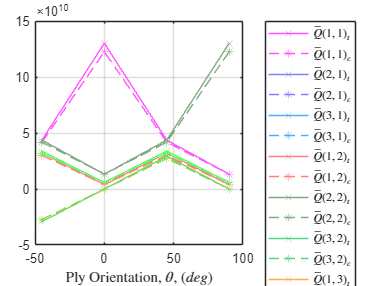


% plot

% plotting variables
Q_bar_plotMat = zeros(3, 3, 2, length(plyOrientations));

% % plotting loop
% for j = 1:3
%     for i = 1:3
%         % plotting colour
%         colour = [1/i, (i+j)/6, 1/j];
%         for k = 1:length(plyOrientations)
%             Q_bar_t = Q_bars_tensile{k}
%             Q_bar_c = Q_bars_compressive{k}
%             orientation = plyOrientations(k)
% 
%             Q_bar_plotMat(i, j, 1, k) = Q_bar_t(i,j);
%             Q_bar_plotMat(i, j, 2, k) = Q_bar_c(i,j);
% 
%             Q_bar_plotMat2(i, :, 1, k) = Q_bar_t(i,:);
%             Q_bar_plotMat2(i, :, 2, k) = Q_bar_c(i,:);
% 
%             if(k==1)
%                 hv = "on";
%             else
%                 hv = "callback";
%             end
% 
%             plot(orientation, Q_bar_t(i,j), "x", "Color",colour, "DisplayName",sprintf("$\\bar{Q}(%g,%g)_t$",i,j), "HandleVisibility",hv)
%             hold on
%             plot(orientation, Q_bar_c(i,j), "*", "Color",colour, "DisplayName",sprintf("$\\bar{Q}(%g,%g)_c$",i,j), "HandleVisibility",hv)
%             hold on
%         end
%     end
% end

% streamlined plotting loop
% saving loop for plotting material values
for k = 1:length(plyOrientations)
    Q_bar_t = Q_bars_tensile{k};
    Q_bar_c = Q_bars_compressive{k};
    orientation = plyOrientations(k);

    Q_bar_plotMat(:, :, 1, k) = Q_bar_t(:,:);
    Q_bar_plotMat(:, :, 2, k) = Q_bar_c(:,:);
end

figure;

% streemlined plotting loop
for j = 1:3
    for i = 1:3
        % plotting colour
        colour = [1/i, (i+j)/6, 1/j];
        plot(rad2deg(plyOrientations),squeeze(Q_bar_plotMat(i,j,1,:)), "-x", "Color",colour, "DisplayName",sprintf("$\\bar{Q}(%g,%g)_t$",i,j));
        hold on
        plot(rad2deg(plyOrientations),squeeze(Q_bar_plotMat(i,j,2,:)), "--*", "Color",colour, "DisplayName",sprintf("$\\bar{Q}(%g,%g)_c$",i,j));
    end
end

xlabel("Ply Orientation, $\theta$, $\left( deg \right)$", "Interpreter", "latex");
grid on;
legend("Interpreter","latex", "Location","eastoutside")


% for debug
% figure;
% i=1;j=1;
% colour = [1/i, (i+j)/6, 1/j];
% plot(rad2deg(plyOrientations),squeeze(Q_bar_plotMat(i,j,1,:)), "-x", "Color",colour, "DisplayName",sprintf("$\\bar{Q}(%g,%g)_t$",i,j));
% hold on
% plot(plyOrientations,squeeze(Q_bar_plotMat(i,j,2,:)), "--*", "Color",colour, "DisplayName",sprintf("$\\bar{Q}(%g,%g)_c$",i,j));
% xlabel("Ply Orientation, $\theta$, $\left( deg \right)$", "Interpreter", "latex");
% grid on;
% legend("Interpreter","latex", "Location","eastoutside")



## HW_4 Problem 2

figure;
for orientationPerturbation = or_perts

    % compute perturnbed anlges
    plyOrientations_pos_pert = plyOrientations + orientationPerturbation;
    plyOrientations_neg_pert = plyOrientations - orientationPerturbation;
    % compute Q_bar at perturbed angles
    Q_bars_tensile_pert = arrayfun(@(T) myPly_tensile.Qbar(T), plyOrientations, "UniformOutput",false);
    Q_bars_compressive_pert = arrayfun(@(T) myPly_compressive.Qbar(T), plyOrientations, "UniformOutput",false);

    % streamlined plotting loop
    % saving loop for plotting material values
    for k = 1:length(plyOrientations)
        Q_bar_t = myPly_tensile.Qbar(plyOrientations_pos_pert(k));
        Q_bar_c = myPly_compressive.Qbar(plyOrientations_pos_pert(k));
        orientation = plyOrientations(k);

        Q_bar_plotMat_posPert_t(:, :, 1, k) = Q_bar_t(:,:);
        Q_bar_plotMat_posPert_c(:, :, 2, k) = Q_bar_c(:,:);
    end

    % extremly lazy way to do the negative perturbation
    for k = 1:length(plyOrientations)
        Q_bar_t = myPly_tensile.Qbar(plyOrientations_neg_pert(k));
        Q_bar_c = myPly_compressive.Qbar(plyOrientations_neg_pert(k));
        orientation = plyOrientations(k);

        Q_bar_plotMat_negPert_t(:, :, 1, k) = Q_bar_t(:,:);
        Q_bar_plotMat_negPert_c(:, :, 2, k) = Q_bar_c(:,:);
    end

    % plot the region and tollerances
    boundaryEdges_Xcoords = [plyOrientations, fliplr(plyOrientations)];
    % streemlined plotting loop
    for j = 1:3
        for i = 1:3
            % plotting colour
            colour = [1/i, (i+j)/6, 1/j];
            %colour = colour * (max(or_perts)-orientationPerturbation/2)/max(or_perts);

            % compute the upper and lower limits of value
            boundaryEdges_Ycoords = [squeeze(Q_bar_plotMat_posPert_t(i,j,1,:)); flipud(squeeze(Q_bar_plotMat_negPert_t(i,j,1,:)))];

            % plot the range of values
            fill(rad2deg(boundaryEdges_Xcoords), boundaryEdges_Ycoords, colour, "FaceAlpha", .25, "EdgeColor", "none", "DisplayName",sprintf("$\\bar{Q}(%g,%g)_t \\pm %g^\\circ$",i,j,rad2deg(orientationPerturbation)));
            hold on
            % plot the Nominal value
            %plot(rad2deg(plyOrientations),squeeze(Q_bar_plotMat(i,j,1,:)), "-x", "Color",colour, "DisplayName",sprintf("$\\bar{Q}(%g,%g)_t$",i,j));

            hold on
            %plot(rad2deg(plyOrientations),squeeze(Q_bar_plotMat(i,j,2,:)), "--*", "Color",colour, "DisplayName",sprintf("$\\bar{Q}(%g,%g)_c$",i,j))
        end

    end

    % compute the width of the perturbations
    for k = 1:length(plyOrientations)
        fprintf("ply orientaion = %g; pert = +- %g", rad2deg(plyOrientations(k)), rad2deg(orientationPerturbation))
        %Q_bar_plotMat(:,:,1,k) - Q_bar_plotMat_negPert_t(:, :, 1, k)
        %Q_bar_plotMat(:,:,1,k) - Q_bar_plotMat_posPert_t(:, :, 1, k)
        Q_bar_plotMat_posPert_t(:, :, 1, k)
        Q_bar_plotMat_negPert_t(:, :, 1, k)
    end

end

ply orientaion = -45; pert = +- 1.5

ans = 1.0e+10 *

    4.6815    3.1882   -3.0648
    3.1882    4.0697   -2.7722
   -3.0648   -2.7722    3.3776


ans = 1.0e+10 *

    4.0697    3.1882   -2.7722
    3.1882    4.6815   -3.0648
   -2.7722   -3.0648    3.3776


ply orientaion = 0; pert = +- 1.5

ans = 1.0e+11 *

    1.2997    0.0404    0.0299
    0.0404    0.1322    0.0007
    0.0299    0.0007    0.0594


ans = 1.0e+11 *

    1.2997    0.0404   -0.0299
    0.0404    0.1322   -0.0007
   -0.0299   -0.0007    0.0594


ply orientaion = 45; pert = +- 1.5

ans = 1.0e+10 *

    4.0697    3.1882    2.7722
    3.1882    4.6815    3.0648
    2.7722    3.0648    3.3776


ans = 1.0e+10 *

    4.6815    3.1882    3.0648
    3.1882    4.0697    2.7722
    3.0648    2.7722    3.3776


ply orientaion = 90; pert = +- 1.5

ans = 1.0e+11 *

    0.1322    0.0404   -0.0007
    0.0404    1.2997   -0.0299
   -0.0007   -0.0299    0.0594


ans = 1.0e+11 *

    0.1322    0.0404    0.0007
    0.0404    1.2997    0.0299
    0.0007    0.0299    0.0594


ply orientaion = -45; pert = +- 3

ans = 1.0e+10 *

    5.0095    3.1652   -3.1975
    3.1652    3.7875   -2.6155
   -3.1975   -2.6155    3.3547


ans = 1.0e+10 *

    3.7875    3.1652   -2.6155
    3.1652    5.0095   -3.1975
   -2.6155   -3.1975    3.3547


ply orientaion = 0; pert = +- 3

ans = 1.0e+11 *

    1.2950    0.0427    0.0596
    0.0427    0.1324    0.0014
    0.0596    0.0014    0.0617


ans = 1.0e+11 *

    1.2950    0.0427   -0.0596
    0.0427    0.1324   -0.0014
   -0.0596   -0.0014    0.0617


ply orientaion = 45; pert = +- 3

ans = 1.0e+10 *

    3.7875    3.1652    2.6155
    3.1652    5.0095    3.1975
    2.6155    3.1975    3.3547


ans = 1.0e+10 *

    5.0095    3.1652    3.1975
    3.1652    3.7875    2.6155
    3.1975    2.6155    3.3547


ply orientaion = 90; pert = +- 3

ans = 1.0e+11 *

    0.1324    0.0427   -0.0014
    0.0427    1.2950   -0.0596
   -0.0014   -0.0596    0.0617


ans = 1.0e+11 *

    0.1324    0.0427    0.0014
    0.0427    1.2950    0.0596
    0.0014    0.0596    0.0617


ply orientaion = -45; pert = +- 4.5

ans = 1.0e+10 *

    5.3508    3.1273   -3.3190
    3.1273    3.5221   -2.4540
   -3.3190   -2.4540    3.3168


ans = 1.0e+10 *

    3.5221    3.1273   -2.4540
    3.1273    5.3508   -3.3190
   -2.4540   -3.3190    3.3168


ply orientaion = 0; pert = +- 4.5

ans = 1.0e+11 *

    1.2872    0.0465    0.0890
    0.0465    0.1326    0.0025
    0.0890    0.0025    0.0655


ans = 1.0e+11 *

    1.2872    0.0465   -0.0890
    0.0465    0.1326   -0.0025
   -0.0890   -0.0025    0.0655


ply orientaion = 45; pert = +- 4.5

ans = 1.0e+10 *

    3.5221    3.1273    2.4540
    3.1273    5.3508    3.3190
    2.4540    3.3190    3.3168


ans = 1.0e+10 *

    5.3508    3.1273    3.3190
    3.1273    3.5221    2.4540
    3.3190    2.4540    3.3168


ply orientaion = 90; pert = +- 4.5

ans = 1.0e+11 *

    0.1326    0.0465   -0.0025
    0.0465    1.2872   -0.0890
   -0.0025   -0.0890    0.0655


ans = 1.0e+11 *

    0.1326    0.0465    0.0025
    0.0465    1.2872    0.0890
    0.0025    0.0890    0.0655


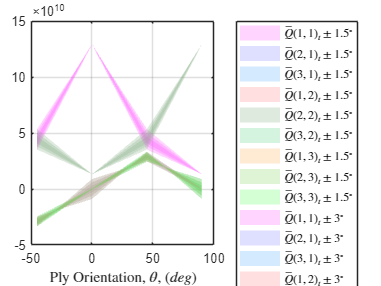

xlabel("Ply Orientation, $\theta$, $\left( deg \right)$", "Interpreter", "latex");
grid on;
legend("Interpreter","latex", "Location","eastoutside")